%% ========================================================================
%  Nonlinear piezoelectric energy harvester with a highly accurate magnetic
%  force model (Yang & Xiang, Nonlinear Dynamics, 2023). The code computes
%  the voltage frequency response of a monostable harvester, comparing the
%  proposed corrected magnetic force model with the traditional point-dipole
%  model. The results reproduce Figures 14 and 15 of the paper.
%
%  Author: Yi Yang
%  Reference: Yang, Y., Xiang, H. (2023). A simple and precise formula for
%             magnetic forces in nonlinear piezoelectric energy harvesting.
%             Nonlinear Dynamics, 111, 6085-6110.
% =========================================================================

clear; clc; close all;

# **1. System parameters (SI units)**

% Beam
L = 68e-3;   bs = 10e-3;   hs = 0.64e-3;
Ys = 68.9e9; rho_s = 2700; xi1 = 0.01;   % damping ratio

% PZT layer (unimorph)
lp = 28e-3;  bp = 7e-3;    hp = 0.3e-3;
e31 = -5.16; Yp = 30.336e9; epsilon = 18.98e-9; rho_p = 5440;

% Magnets (cylinder)
MA = 891e3;  MB = MA;
R = 5e-3;    T_full = 5e-3;          % full thickness = 5 mm
T_half = T_full/2;                    % half thickness
VA = pi*R^2*T_full;  VB = VA;
Mt = 9e-3;
miu0 = 4*pi*1e-7;

% Excitation
AMP = 2.83;   % base acceleration 2 m/s^2 (rms)

% Interface circuit
RL = 1e6;     % load resistance (Ω)


# **2. Cross-sectional properties**

As = hs*bs;
Ap = hp*bp;

% Neutral axis (unimorph)
hc = (Ys*As*hs + Yp*Ap*(2*hs+hp)) / (2*(Ys*As+Yp*Ap));
Is1 = 1/3*bs*((hs-hc)^3 + hc^3);
Ip  = 1/3*bp*((hp+hs-hc)^3 - (hs-hc)^3);
m01 = rho_s*bs*hs + rho_p*bp*hp;
EI1 = Ys*Is1 + Yp*Ip;
Cp = epsilon*lp*bp/hp;

% Pure beam part (without PZT)
Is2 = 1/12*bs*hs^3;
EI2 = Ys*Is2;
m02 = rho_s*bs*hs;

% Rotational inertia of end magnet (cylinder)
It = 1/4*Mt*R^2 + 1/3*Mt*T_full^2;


# **3. Efficient modal analysis (first mode)**

beta_coeff2 = (EI1/m01 * m02/EI2)^(1/4);

% Scan for characteristic equation zeros
beta_scan = linspace(0.1, 100, 500);
f_scan = zeros(size(beta_scan));
for i = 1:length(beta_scan)
    f_scan(i) = det(A_matrix(beta_scan(i), L, lp, EI1, EI2, m01, It, Mt, beta_coeff2));
end
zero_crossings = find(diff(sign(f_scan)));
if isempty(zero_crossings)
    error('No zero crossing found – increase scan range');
end
first_zero_interval = [beta_scan(zero_crossings(1)), beta_scan(zero_crossings(1)+1)];

f = @(beta) det(A_matrix(beta, L, lp, EI1, EI2, m01, It, Mt, beta_coeff2));
options = optimset('Display','off', 'TolFun',1e-8);
eigen_beta1 = fzero(f, first_zero_interval, options);

w1 = eigen_beta1^2 * sqrt(EI1/m01);
freq1 = w1/(2*pi);
fprintf('First natural frequency = %.3f Hz\n', freq1);

First natural frequency = 24.784 Hz


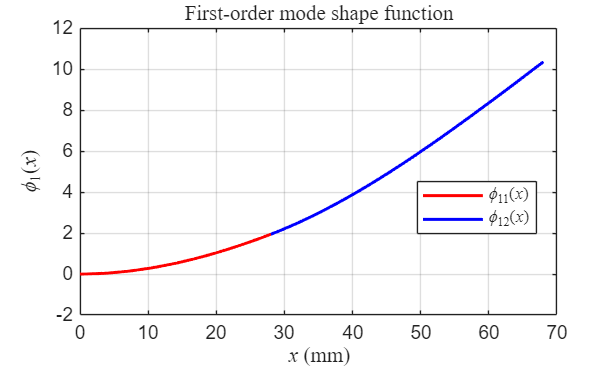


% Normalized mode shapes
beta1 = eigen_beta1;
beta2 = beta1 * beta_coeff2;

A_val = A_matrix(beta1, L, lp, EI1, EI2, m01, It, Mt, beta_coeff2);
A_reduced = A_val(2:8, 2:8);
b_A = -A_val(2:8, 1);
C_other = A_reduced \ b_A;
C_vec = [1; C_other];

phi1 = @(x) C_vec(1)*cos(beta1*x) + C_vec(2)*sin(beta1*x) + ...
            C_vec(3)*cosh(beta1*x) + C_vec(4)*sinh(beta1*x);
phi2 = @(x) C_vec(5)*cos(beta2*x) + C_vec(6)*sin(beta2*x) + ...
            C_vec(7)*cosh(beta2*x) + C_vec(8)*sinh(beta2*x);

% Numerical integration for generalized mass
mass_int1 = m01 * integral(@(x) phi1(x).^2, 0, lp, 'ArrayValued', true, 'RelTol',1e-10);
mass_int2 = m02 * integral(@(x) phi2(x).^2, lp, L, 'ArrayValued', true, 'RelTol',1e-10);
dphi2 = @(x) beta2*(-C_vec(5)*sin(beta2*x) + C_vec(6)*cos(beta2*x) + ...
                    C_vec(7)*sinh(beta2*x) + C_vec(8)*cosh(beta2*x));
dphi2_L = dphi2(L);
mass_end = Mt * phi2(L)^2 + It * dphi2_L^2;
mass_total = mass_int1 + mass_int2 + mass_end;
k_norm = 1 / sqrt(mass_total);
C_vec_norm = C_vec * k_norm;

phi1_norm = @(x) C_vec_norm(1)*cos(beta1*x) + C_vec_norm(2)*sin(beta1*x) + ...
                 C_vec_norm(3)*cosh(beta1*x) + C_vec_norm(4)*sinh(beta1*x);
phi2_norm = @(x) C_vec_norm(5)*cos(beta2*x) + C_vec_norm(6)*sin(beta2*x) + ...
                 C_vec_norm(7)*cosh(beta2*x) + C_vec_norm(8)*sinh(beta2*x);
dphi1_norm = @(x) beta1*(-C_vec_norm(1)*sin(beta1*x) + C_vec_norm(2)*cos(beta1*x) + ...
                         C_vec_norm(3)*sinh(beta1*x) + C_vec_norm(4)*cosh(beta1*x));
dphi2_norm = @(x) beta2*(-C_vec_norm(5)*sin(beta2*x) + C_vec_norm(6)*cos(beta2*x) + ...
                         C_vec_norm(7)*sinh(beta2*x) + C_vec_norm(8)*cosh(beta2*x));

if phi1_norm(lp) < 0
    C_vec_norm = -C_vec_norm;
    phi1_norm = @(x) C_vec_norm(1)*cos(beta1*x) + C_vec_norm(2)*sin(beta1*x) + ...
                     C_vec_norm(3)*cosh(beta1*x) + C_vec_norm(4)*sinh(beta1*x);
    phi2_norm = @(x) C_vec_norm(5)*cos(beta2*x) + C_vec_norm(6)*sin(beta2*x) + ...
                     C_vec_norm(7)*cosh(beta2*x) + C_vec_norm(8)*sinh(beta2*x);
    dphi1_norm = @(x) beta1*(-C_vec_norm(1)*sin(beta1*x) + C_vec_norm(2)*cos(beta1*x) + ...
                             C_vec_norm(3)*sinh(beta1*x) + C_vec_norm(4)*cosh(beta1*x));
    dphi2_norm = @(x) beta2*(-C_vec_norm(5)*sin(beta2*x) + C_vec_norm(6)*cos(beta2*x) + ...
                             C_vec_norm(7)*sinh(beta2*x) + C_vec_norm(8)*cosh(beta2*x));
end

faiL = phi2_norm(L);
DfaiL = dphi2_norm(L);

% Electromechanical coupling factor theta1
dphi_at_lp = dphi1_norm(lp);
theta1 = 0.5*(hp + 2*hs - 2*hc)*e31*bp*dphi_at_lp;
theta1 = double(theta1);

% Excitation factor gamma1
integral_M1 = m01 * integral(phi1_norm, 0, lp, 'ArrayValued', true, 'RelTol',1e-8);
integral_M2 = m02 * integral(phi2_norm, lp, L, 'ArrayValued', true, 'RelTol',1e-8);
end_M = Mt * faiL;
gamma1 = abs(integral_M1 + integral_M2 + end_M);

% Equivalent single-DOF parameters (mass normalized to 1)
M = 1;                % generalized mass = 1 after normalization
K0 = w1^2;            % linear stiffness

% Plot mode shape
figure;
x1 = linspace(0, lp, 200);  x2 = linspace(lp, L, 200);
y1 = arrayfun(phi1_norm, x1);
y2 = arrayfun(phi2_norm, x2);
plot(1e3*x1, y1, 'r-', 'LineWidth',1.5); hold on;
plot(1e3*x2, y2, 'b-', 'LineWidth',1.5);
legend('\phi_{11}(\itx\rm)','\phi_{12}(\itx\rm)','FontName','Times New Roman','Location','best');
xlabel('\itx\rm (mm)','FontName','Times New Roman');
ylabel('\phi_1(\itx\rm)','FontName','Times New Roman');
title('First-order mode shape function','FontName','Times New Roman');
grid on;

# **4. Magnetic force (d = 15 mm)**

d_mag = 15e-3;
kappa = miu0 * MA * MB * VA * VB / (4 * pi);
[alpha_m, beta_m, ~] = correct_cylindermagnet_coeff(MA, R, T_half, d_mag);

历时 0.327199 秒。


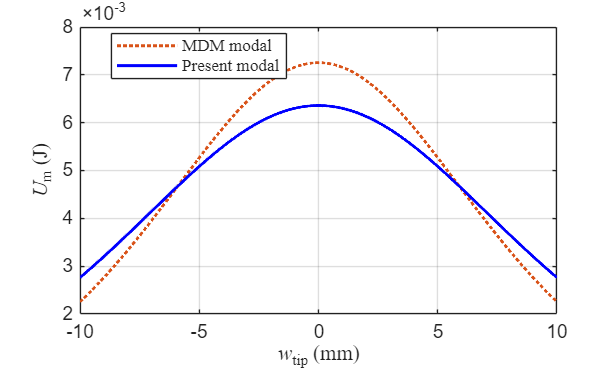


% Coefficients for Taylor expansion (as in original)
k1 = alpha_m * beta_m^2 * kappa * (-12 * faiL^2) / d_mag^5;
k2 = 12 * alpha_m * beta_m^4 * kappa * (3.75 * faiL^4) / d_mag^7;
% Original MDM coefficients
k01 = kappa * (-12 * faiL^2) / d_mag^5;
k02 = 12 * kappa * (3.75 * faiL^4) / d_mag^7;

% Magnetic potential and force (for figures)
num0 = 2001;
q = linspace(-0.01/faiL, 0.01/faiL, num0);
Um0 = kappa * ((-faiL^2*q.^2 + 2*d_mag^2) ./ (d_mag^2 + (faiL*q).^2).^2.5);
Um = alpha_m * kappa * ((-faiL^2*q.^2*beta_m^2 + 2*d_mag^2) ./ (d_mag^2 + (faiL*q*beta_m).^2).^2.5);

figure;
plot(q*faiL*1e3, Um0, ':', 'Color','#D95319','LineWidth',1.5); hold on;
plot(q*faiL*1e3, Um, 'b-','LineWidth',1.5);
xlabel('\itw_{\rmtip}\rm (mm)','FontName','Times New Roman');
ylabel('\itU_{\rmm}\rm (J)','FontName','Times New Roman');
legend('MDM modal','Present modal','FontName','Times New Roman','Location','best');
grid on;


Fm0 = -diff(Um0)./diff(q*faiL);
Fm  = -diff(Um)./diff(q*faiL);
w_tip_mid = 0.5*(q(1:end-1)+q(2:end))*faiL;
Fm1 = -(k1*q + k2*q.^3)/faiL;   % Taylor expansion of present model

% Load reference data if exists
if exist('Magnetic force_Upadrashta.xlsx','file')
    data_ref = readtable('Magnetic force_Upadrashta.xlsx');
    data_ref = table2array(data_ref);
else
    data_ref = [];
end

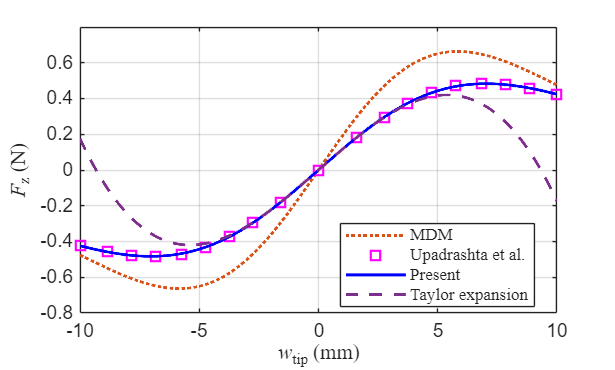


figure;
plot(w_tip_mid*1e3, Fm0, ':', 'Color','#D95319','LineWidth',1.5); hold on;
if ~isempty(data_ref)
    plot(data_ref(:,1), data_ref(:,2), 'ms','LineWidth',1.5);
end
plot(w_tip_mid*1e3, Fm, 'b-','LineWidth',1.5);
plot(q*faiL*1e3, Fm1, '--','Color',[0.4940 0.1840 0.5560],'LineWidth',1.5);
xlabel('\itw_{\rmtip}\rm (mm)','FontName','Times New Roman');
ylabel('\itF_{\rmz}\rm (N)','FontName','Times New Roman');
legend('MDM','Upadrashta et al.','Present','Taylor expansion',...
       'FontName','Times New Roman','Location','best');
grid on;

# **5. Frequency response**

% Damping coefficient
xi_phys = xi1 * w1;   % = damping ratio * natural frequency

% Frequency range (Hz) from 8 to 24
freq_Hz = linspace(8, 24, 401);
omega = freq_Hz * 2*pi;

% Storage for present model
freq_present_high = []; volt_present_high = [];
freq_present_low  = []; volt_present_low  = [];
freq_present_unstable = []; volt_present_unstable = [];

% Storage for MDM model
freq_mdm_high = []; volt_mdm_high = [];
freq_mdm_low  = []; volt_mdm_low  = [];
freq_mdm_unstable = []; volt_mdm_unstable = [];

% Define symbolic variable eta (amplitude in generalized coordinate)
syms eta real

% Helper function to compute voltage RMS from eta
voltage_rms = @(w, eta) RL * abs(theta1) * w / sqrt(1 + Cp^2 * w^2 * RL^2) * eta / sqrt(2);

% Waitbar
hWaitbar = waitbar(0, 'Computing frequency response (Present model)...', 'Name', 'Amplitude equation');

% For present model
bistable_encountered = false;   % flag if bistable region has been entered
bistable_end_freq = [];          % last frequency where 3 solutions exist

for i = 1:length(omega)
    w = omega(i);
    
    K_e = (theta1^2 * w^2 * RL^2 * Cp) / (1 + Cp^2 * w^2 * RL^2);
    C_e = (w * RL * theta1^2) / (1 + Cp^2 * w^2 * RL^2);
    
    eqn_present = eta^2 * ( (w1^2 - abs(k1) - w^2 + 0.75*k2*eta^2 + K_e)^2 ...
                         + (2*xi_phys*w + C_e)^2 ) - (gamma1*AMP)^2 == 0;
    
    sol = vpasolve(eqn_present, eta);
    eta_sol = double(sol);
    eta_sol = eta_sol(imag(eta_sol)==0);
    eta_sol = eta_sol(eta_sol > 0);
    eta_sol = sort(eta_sol);
    
    n_sol = length(eta_sol);
    
    if n_sol == 3
        % Bistable region
        bistable_encountered = true;
        bistable_end_freq = freq_Hz(i);   % update end frequency
        % Upper branch (largest amplitude)
        freq_present_high = [freq_present_high; freq_Hz(i)];
        volt_present_high = [volt_present_high; voltage_rms(w, eta_sol(3))];
        % Lower branch (smallest amplitude)
        freq_present_low = [freq_present_low; freq_Hz(i)];
        volt_present_low = [volt_present_low; voltage_rms(w, eta_sol(1))];
        % Unstable branch (middle)
        freq_present_unstable = [freq_present_unstable; freq_Hz(i)];
        volt_present_unstable = [volt_present_unstable; voltage_rms(w, eta_sol(2))];
        
    elseif n_sol == 1
        % Single stable solution
        if bistable_encountered && freq_Hz(i) > bistable_end_freq
            % After bistable region -> low energy branch
            freq_present_low = [freq_present_low; freq_Hz(i)];
            volt_present_low = [volt_present_low; voltage_rms(w, eta_sol(1))];
        else
            % Before bistable region (or never entered bistable) -> high energy branch
            freq_present_high = [freq_present_high; freq_Hz(i)];
            volt_present_high = [volt_present_high; voltage_rms(w, eta_sol(1))];
        end
    end
    
    waitbar(i/length(omega), hWaitbar, sprintf('Present: %.1f Hz, %.1f%%', freq_Hz(i), 100*i/length(omega)));
end

% MDM model
waitbar(0, hWaitbar, 'Computing frequency response (MDM model)...');
bistable_encountered = false;
bistable_end_freq = [];

for i = 1:length(omega)
    w = omega(i);
    
    K_e = (theta1^2 * w^2 * RL^2 * Cp) / (1 + Cp^2 * w^2 * RL^2);
    C_e = (w * RL * theta1^2) / (1 + Cp^2 * w^2 * RL^2);
    
    eqn_mdm = eta^2 * ( (w1^2 - abs(k01) - w^2 + 0.75*k02*eta^2 + K_e)^2 ...
                     + (2*xi_phys*w + C_e)^2 ) - (gamma1*AMP)^2 == 0;
    
    sol = vpasolve(eqn_mdm, eta);
    eta_sol = double(sol);
    eta_sol = eta_sol(imag(eta_sol)==0);
    eta_sol = eta_sol(eta_sol > 0);
    eta_sol = sort(eta_sol);
    
    n_sol = length(eta_sol);
    
    if n_sol == 3
        bistable_encountered = true;
        bistable_end_freq = freq_Hz(i);
        freq_mdm_high = [freq_mdm_high; freq_Hz(i)];
        volt_mdm_high = [volt_mdm_high; voltage_rms(w, eta_sol(3))];
        freq_mdm_low = [freq_mdm_low; freq_Hz(i)];
        volt_mdm_low = [volt_mdm_low; voltage_rms(w, eta_sol(1))];
        freq_mdm_unstable = [freq_mdm_unstable; freq_Hz(i)];
        volt_mdm_unstable = [volt_mdm_unstable; voltage_rms(w, eta_sol(2))];
        
    elseif n_sol == 1
        if bistable_encountered && freq_Hz(i) > bistable_end_freq
            freq_mdm_low = [freq_mdm_low; freq_Hz(i)];
            volt_mdm_low = [volt_mdm_low; voltage_rms(w, eta_sol(1))];
        else
            freq_mdm_high = [freq_mdm_high; freq_Hz(i)];
            volt_mdm_high = [volt_mdm_high; voltage_rms(w, eta_sol(1))];
        end
    end
    
    waitbar(i/length(omega), hWaitbar, sprintf('MDM: %.1f Hz, %.1f%%', freq_Hz(i), 100*i/length(omega)));
end
close(hWaitbar);

% Load reference frequency response data (voltage vs frequency, from Excel)
if exist('FR_Upadrashta.xlsx','file')
    ref_data = readtable('FR_Upadrashta.xlsx');
    ref_data = table2array(ref_data);
else
    ref_data = [];
end


%% Plot voltage frequency response (comparison between MDM and Present)
figure; hold on;

% Present model: stable (all blue solid lines)
if ~isempty(freq_present_high)
    plot(freq_present_high, volt_present_high, 'b-', 'LineWidth', 1.5, ...
         'DisplayName', 'Present (stable)');
end
if ~isempty(freq_present_low)
    plot(freq_present_low, volt_present_low, 'b-', 'LineWidth', 1.5, ...
         'HandleVisibility', 'off');   % do not add to legend
end
% Present unstable (blue dashed)
if ~isempty(freq_present_unstable)
    plot(freq_present_unstable, volt_present_unstable, 'b--', 'LineWidth', 1.2, ...
         'DisplayName', 'Present (unstable)');
end

% MDM model: stable (all red solid lines)
if ~isempty(freq_mdm_high)
    plot(freq_mdm_high, volt_mdm_high, 'r-', 'LineWidth', 1.5, ...
         'DisplayName', 'MDM (stable)');
end
if ~isempty(freq_mdm_low)
    plot(freq_mdm_low, volt_mdm_low, 'r-', 'LineWidth', 1.5, ...
         'HandleVisibility', 'off');
end
% MDM unstable (red dashed)
if ~isempty(freq_mdm_unstable)
    plot(freq_mdm_unstable, volt_mdm_unstable, 'r--', 'LineWidth', 1.2, ...
         'DisplayName', 'MDM (unstable)');
end

% Reference data (if available)
if exist('FR_Upadrashta.xlsx','file')
    ref_data = readtable('FR_Upadrashta.xlsx');
    ref_data = table2array(ref_data);
    if ~isempty(ref_data) && size(ref_data,2) >= 2
        plot(ref_data(:,1), ref_data(:,2), 'ms', 'MarkerSize', 6, 'LineWidth', 1, ...
             'DisplayName', 'Upadrashta et al.');
    end
end

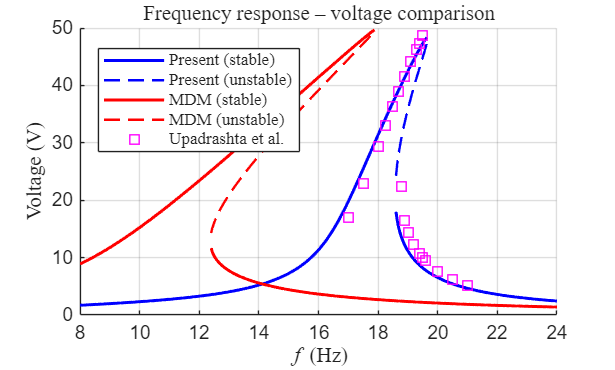


xlabel('\itf\rm (Hz)', 'FontName', 'Times New Roman');
ylabel('Voltage (V)', 'FontName', 'Times New Roman');
title('Frequency response – voltage comparison', 'FontName', 'Times New Roman');
legend('Location', 'best', 'FontName', 'Times New Roman');
grid on;
xlim([8,24]);
hold off;